# Approximate solving of non-linear equations (root finding methods)

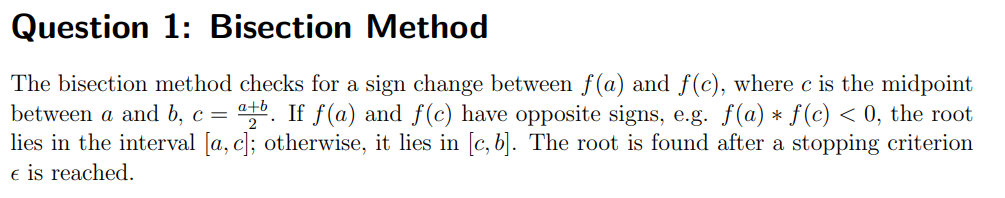

**Bisection method **is a method where you can find a root by cutting the interval into half and checking which half contains the root. The close enough you get to the root, the mode halfs will be created

Iteration 1: x = 3.00000000
Iteration 2: x = 4.50000000
Iteration 3: x = 3.75000000
Iteration 4: x = 4.12500000
Iteration 5: x = 4.31250000
Iteration 6: x = 4.21875000
Iteration 7: x = 4.17187500
Iteration 8: x = 4.14843750
Iteration 9: x = 4.13671875
Iteration 10: x = 4.14257812
Iteration 11: x = 4.13964844
Iteration 12: x = 4.14111328
Iteration 13: x = 4.14111328


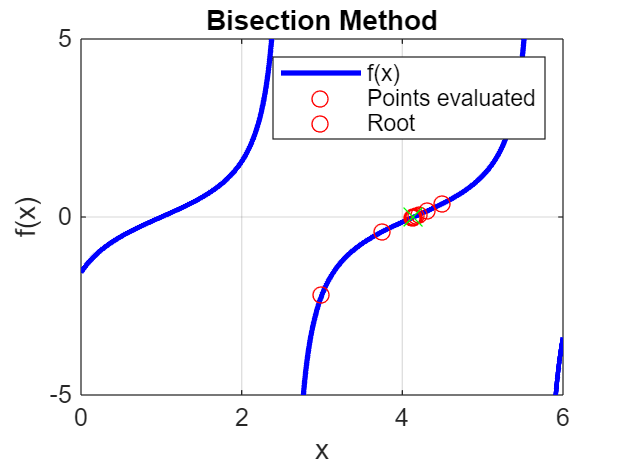

syms x;
f = @(x) tan(x-1);
a = 0;
b = 6;
epsilon = 0.001;
n_max = 100;
OutIterations = true;
tg=true; 

[root, n] = bisection_method(f, a, b, epsilon, n_max, OutIterations, tg);

fprintf('Iterations:%d\nResult: x = %.8f\n',n, root);

Iterations:13
Result: x = 4.14184570


Iteration 1: x = 2.50000000
Iteration 2: x = 1.75000000
Iteration 3: x = 1.37500000
Iteration 4: x = 1.18750000
Iteration 5: x = 1.09375000
Iteration 6: x = 1.04687500
Iteration 7: x = 1.02343750
Iteration 8: x = 1.01171875
Iteration 9: x = 1.00585938
Iteration 10: x = 1.00292969
Iteration 11: x = 1.00146484
Iteration 12: x = 1.00146484


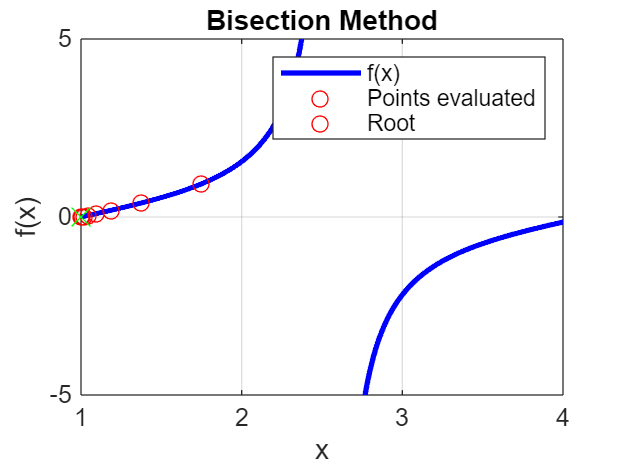


a=1;
b=4;
[root, n] = bisection_method(f, a, b, epsilon, n_max, OutIterations, tg);

fprintf('Iterations:%d\nResult: x = %.8f\n',n, root);

Iterations:12
Result: x = 1.00073242


Observations:

- The functions converges to the second root because of the first iteration. when we are taking interval [a,c] the functions f in points a and c takes negative sign, that causes the a variable to take value of c. First root is equal to 1 and it is not included in a new interval [a=c,b]. 

- Taking the interval [1,4] causes the method to come close the first root out the function in the previous interval. Now root equal to 1 is  the only root of this interval.

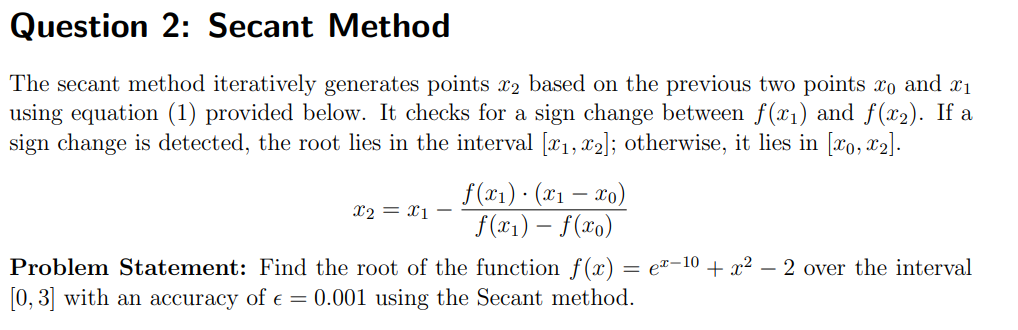

**Secant method **allows us to find a root by creating "lines" on function. Choosing two different points on X-axis and drawing a line which connects them, we update the chosen point in place where the created line crosses the X-axis. The mode secant we draw, the more accurate value of the root we can find

Iteration 1: x = 0.66658736
Iteration 2: x = 1.09080285
Iteration 3: x = 1.55169266
Iteration 4: x = 1.39731667
Iteration 5: x = 1.41336251
Iteration 6: x = 1.41415224
Iteration 7: x = 1.41415224


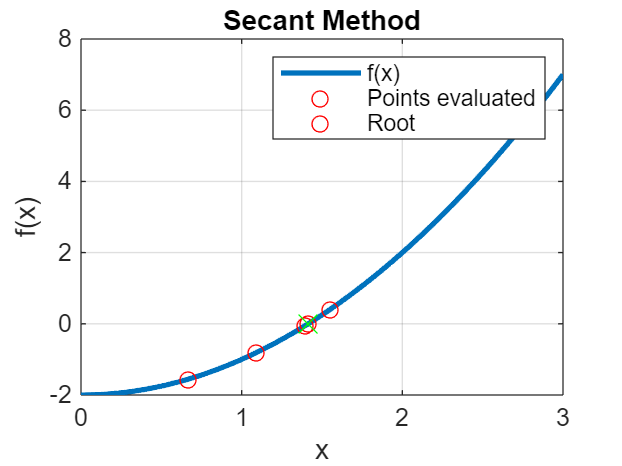

g = @(x) exp(x-10)+x.^2-2;
x0 = 0;
x1 = 3;
[root, n] = secant_method(g, x0, x1, epsilon, n_max, OutIterations);


fprintf('Iterations:%d\nResult: x = %.8f\n',n, root);

Iterations:7
Result: x = 1.41415224


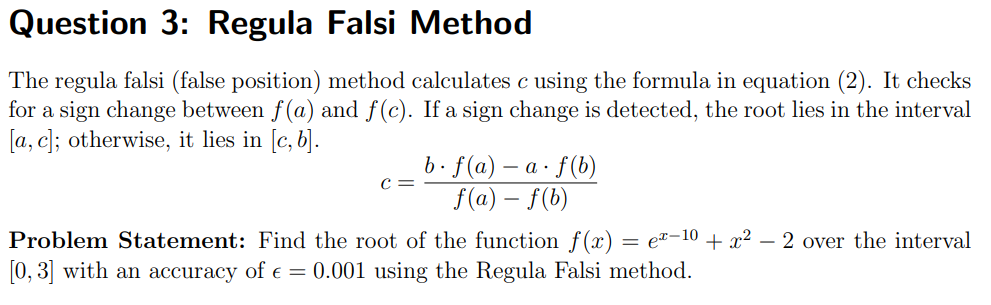

**Regula Falsi method **is a similar method to the bisection one. Instead of splitting the interval in half each time, we use the point where the straight line connecting tho function values crosses the X-axis. We are narrowing down to the place where root lies.

Iteration 1: x = 0.66658736
Iteration 2: x = 1.09080285
Iteration 3: x = 1.28879173
Iteration 4: x = 1.36779222
Iteration 5: x = 1.39731581
Iteration 6: x = 1.40807693
Iteration 7: x = 1.41196343
Iteration 8: x = 1.41336242
Iteration 9: x = 1.41386541
Iteration 10: x = 1.41386541


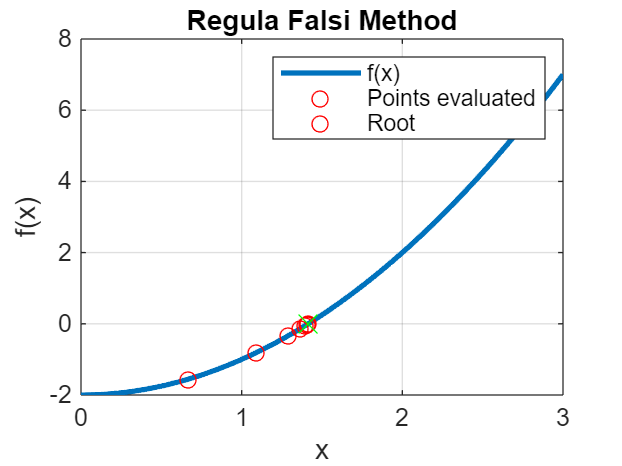

[root, n] = regula_falsi_method(g, x0, x1, epsilon, n_max, OutIterations);

fprintf('Iterations:%d\nResult: x = %.8f\n',n, root);

Iterations:10
Result: x = 1.41386541


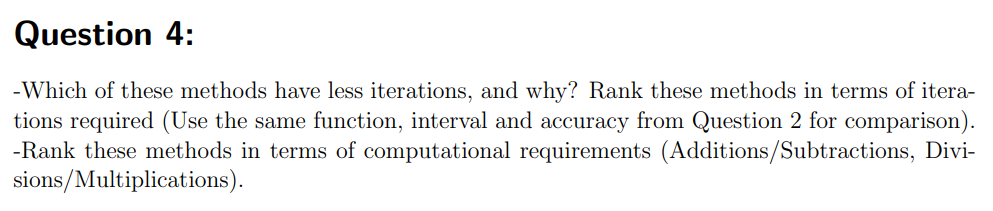

OutIterations = false;
tg = false;
Table = zeros(3,3);
Avg = zeros(3,3);
k = 10;

disp('Tables of results:');

Tables of results:


fprintf('Solving Time [s] | Number of iterations | Root value');

Solving Time [s] | Number of iterations | Root value


for i = 1:k
    tic;
    [root, n] = bisection_method(g, x0, x1, epsilon, n_max, OutIterations,tg);
    Table(1,1)=toc;
    Table(1,2)=n;
    Table(1,3) = root;
    Avg(1,1)=toc;
    Avg(1,2)=n;
    Avg(1,3) = root;
    
    tic;
    [root, n] = secant_method(g, x0, x1, epsilon, n_max, OutIterations);
    Table(2,1)=toc;
    Table(2,2)=n;
    Table(2,3) = root;
    Avg(2,1)=toc;
    Avg(2,2)=n;
    Avg(2,3) = root;
    
    tic;
    [root, n] = regula_falsi_method(g, x0, x1, epsilon, n_max, OutIterations);
    Table(3,1)=toc;
    Table(3,2)=n;
    Table(3,3) = root;
    Avg(3,1)=toc;
    Avg(3,2)=n;
    Avg(3,3) = root;
    
    [nRows, nCols] = size(Table);

    col1_width = 10;
    col2_width = 4;
    col3_width = 9;

    format_row = sprintf('%%-%d.4g | %%%dd | %%%d.6g\n', col1_width, col2_width, col3_width);
    
    for j = 1:nRows
        fprintf(format_row, Table(j,1), Table(j,2), Table(j,3));
    end
    fprintf('-----------------------------');
end 

0.001195   |   12 |   1.41431
0.001694   |    7 |   1.41415
0.001702   |   10 |   1.41387


-----------------------------

0.0002993  |   12 |   1.41431
0.0002503  |    7 |   1.41415
0.000268   |   10 |   1.41387


-----------------------------

0.00233    |   12 |   1.41431
0.0002602  |    7 |   1.41415
0.0001717  |   10 |   1.41387


-----------------------------

0.0001428  |   12 |   1.41431
0.002594   |    7 |   1.41415
0.0008669  |   10 |   1.41387


-----------------------------

0.0001898  |   12 |   1.41431
0.0001202  |    7 |   1.41415
0.0005823  |   10 |   1.41387


-----------------------------

1.1e-05    |   12 |   1.41431
5.5e-06    |    7 |   1.41415
8.7e-06    |   10 |   1.41387


-----------------------------

7.1e-06    |   12 |   1.41431
3.3e-06    |    7 |   1.41415
5.12e-05   |   10 |   1.41387


-----------------------------

5.8e-06    |   12 |   1.41431
3.5e-06    |    7 |   1.41415
5.2e-06    |   10 |   1.41387


-----------------------------

4.4e-06    |   12 |   1.41431
2.4e-06    |    7 |   1.41415
4.7e-06    |   10 |   1.41387


-----------------------------

3.8e-06    |   12 |   1.41431
2.3e-06    |    7 |   1.41415
8.1e-06    |   10 |   1.41387


-----------------------------


fprintf('Bisection method average solving time: %.1f us', 1000000*Avg(1,1)/k);

Bisection method average solving time: 0.5 us

fprintf('Secant method average solving time: %.1f us', 1000000*Avg(2,1)/k);

Secant method average solving time: 0.2 us

fprintf('Regula Falsi method average solving time: %.1f us', 1000000*Avg(3,1)/k);

Regula Falsi method average solving time: 0.9 us

Observations:

- The Secant method exhibits both the lowest number of iterations and the shortest solving time. This efficiency is attributed to the method's ability to create smaller intervals compared to the first and third methods. 

- Although the first method involves simpler equations and thus requires less computational effort per iteration, it necessitates a significantly higher number of iterations to converge to a result. 

- Consequently, despite the simplicity of individual computations in the first method, the overall solving time is greater due to the increased number of iterations required.

- All of the observations mentioned above are also influenced by the implementation of these methods and the capabilities of the computer used, which can contribute to incorrect assessments of the efficiencies of these methods.

Ranking:

- Secant method

- Bisection method

- Regula Falsi method

function [root, n] = bisection_method(f, a, b, epsilon, n_max, OutIterations,tg)    
    n = 1;
    if(OutIterations)
        if(tg)
            x = linspace(a, 2.57, 1000);
            y = f(x);
            plot(x, y, 'LineWidth', 2, 'Color', 'b');
            hold on;
    
            x = linspace(2.58, 5.6, 1000);
            y = f(x);
            plot(x, y, 'LineWidth', 2, 'Color', 'b');
            hold on;
    
            if(5.8<b)
                x = linspace(5.8, b, 1000);
                y = f(x);
                plot(x, y, 'LineWidth', 2, 'Color', 'b');
                hold on;
            end
        else
            x = linspace(a, b, 1000);
            y = f(x);
            plot(x, y, 'LineWidth', 2, 'Color', 'b');
            hold on;
        end
        ylim([-5 5]);
        xlim([a b]);
    end
    while (b - a) / 2 > epsilon
        c = (a + b) / 2;
        if(OutIterations)
            fprintf("Iteration %.d: x = %.8f\n",n,c);
            plot(c, f(c), 'ro');
        end
        if f(c) == 0
            root = c;
            return;
        elseif f(c) * f(a) <= 0
            b = c;
        else
            a = c;
        end
        n = n + 1;
        if n >= n_max
            error('The maximum number of iterations has been exceeded.');
        end
    end
    root = (a + b) / 2; 
    if(OutIterations)
        fprintf("Iteration %.d: x = %.8f\n",n,c);

        plot(root, f(root), 'gx', 'MarkerSize', 10); 
        xlabel('x');
        ylabel('f(x)');
        title('Bisection Method');
        legend('f(x)','','', 'Points evaluated', 'Root');
        grid on;
        
        hold off;
    end
end

function [root, iterations] = secant_method(f, x0, x1, epsilon, max_iterations, OutIterations)
    iterations = 1;
    if(OutIterations)
        x = linspace(x0, x1, 1000);
        y = f(x);
        plot(x, y, 'LineWidth', 2);
        hold on;
    end
    while abs(f(x1)) > epsilon
        x2 = x1 - f(x1) * (x1 - x0) / (f(x1) - f(x0));
        x0 = x1;
        x1 = x2;
        if(OutIterations)
            fprintf("Iteration %.d: x = %.8f\n",iterations,x1);
            plot(x1, f(x1), 'ro');
        end
        iterations = iterations + 1;
        if iterations >= max_iterations
            error('The maximum number of iterations has been exceeded.');
        end
    end
    root = x1;
    if(OutIterations)
        fprintf("Iteration %.d: x = %.8f\n",iterations,x1);

        plot(root, f(root), 'gx', 'MarkerSize', 10); 
        xlabel('x');
        ylabel('f(x)');
        title('Secant Method');
        legend('f(x)', 'Points evaluated', 'Root');
        grid on;
        
        hold off;
    end
end

function [root, n] = regula_falsi_method(f, a, b, epsilon, n_max, OutIterations)
    n = 1;
    loop = true;
    if(OutIterations)
        x = linspace(a, b, 1000);
        y = f(x);
        plot(x, y, 'LineWidth', 2);
        hold on;
    end
    while loop 
        c = (a * f(b) - b * f(a)) / (f(b) - f(a));
        if(OutIterations)
            fprintf("Iteration %.d: x = %.8f\n",n,c);
            plot(c, f(c), 'ro');
        end
        if f(c) == 0
            root = c;
            return;
        elseif f(c) * f(a) < 0
            b = c;
        else
            a = c;
        end
        if(abs(f(c))< epsilon)
            loop = false;
        end
        n = n + 1;
        if n >= n_max
            error('The maximum number of iterations has been exceeded.');
        end
    end
    root = c;
    if(OutIterations)
        fprintf("Iteration %.d: x = %.8f\n",n,c);
        
        plot(root, f(root), 'gx', 'MarkerSize', 10); 
        xlabel('x');
        ylabel('f(x)');
        title('Regula Falsi Method');
        legend('f(x)', 'Points evaluated', 'Root');
        grid on;
        
        hold off;
    end
end